**1D case: electric potential and electric field are calculated at distance d from the origin**

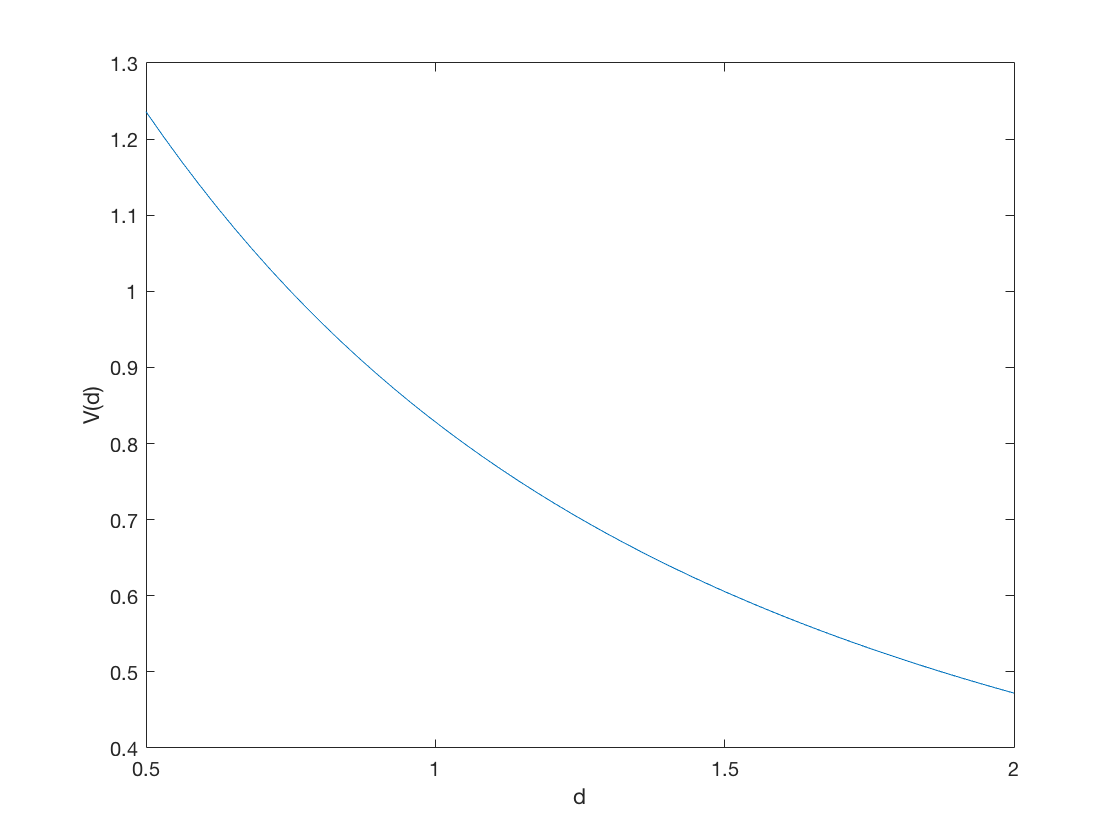

d=linspace(0.5,2,50);
xp=linspace(0,1,100);
f= @(x,xp) 2 .* xp./sqrt(x.^2+xp.^2);

v=[];
for obj=d(1:length(d))
    v=[v,trapz(xp,f(obj,xp))];

end 
   
plot(d,v)
xlabel('d')
ylabel('V(d)')

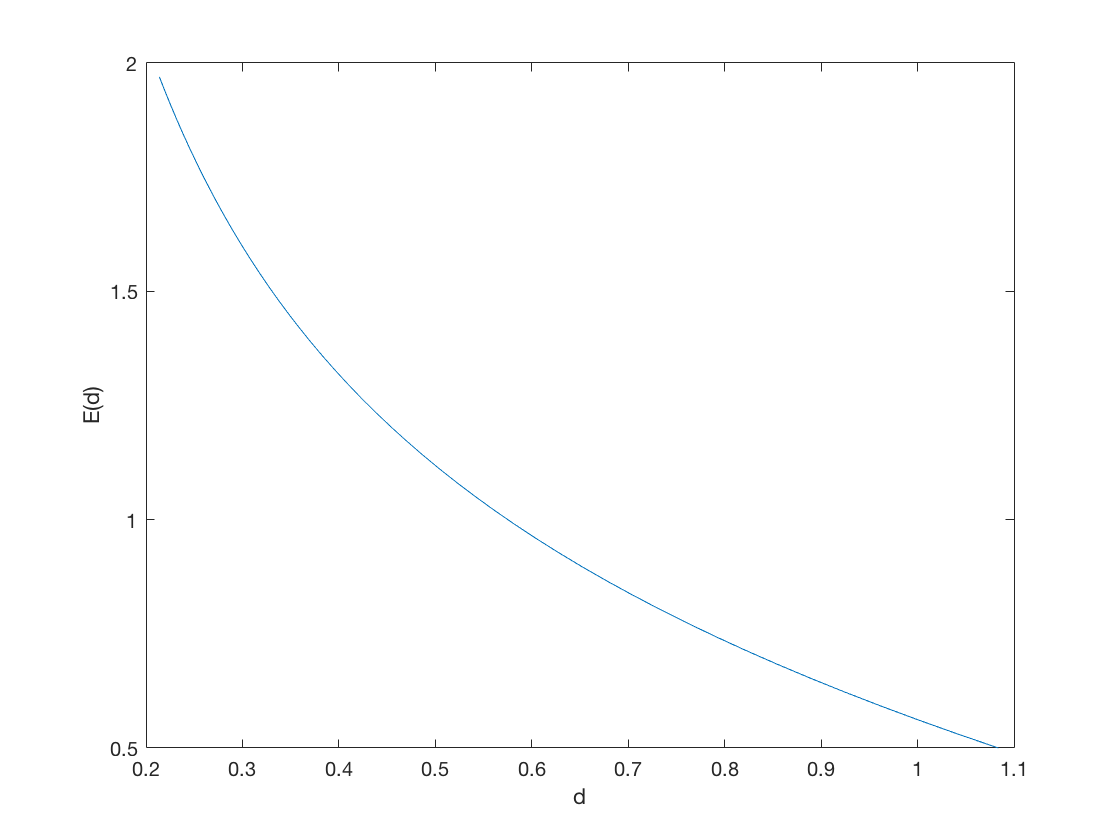


E=-diff(v)./diff(d);
plot(E,d(1:49))
xlabel('d')
ylabel('E(d)')

**2D case: electric potential and electric field are calculated at point (x,y) in x-y plane. **

**total poteintial is the sum of potential due to charge distribution on x axis and charge distribution on y axis.**

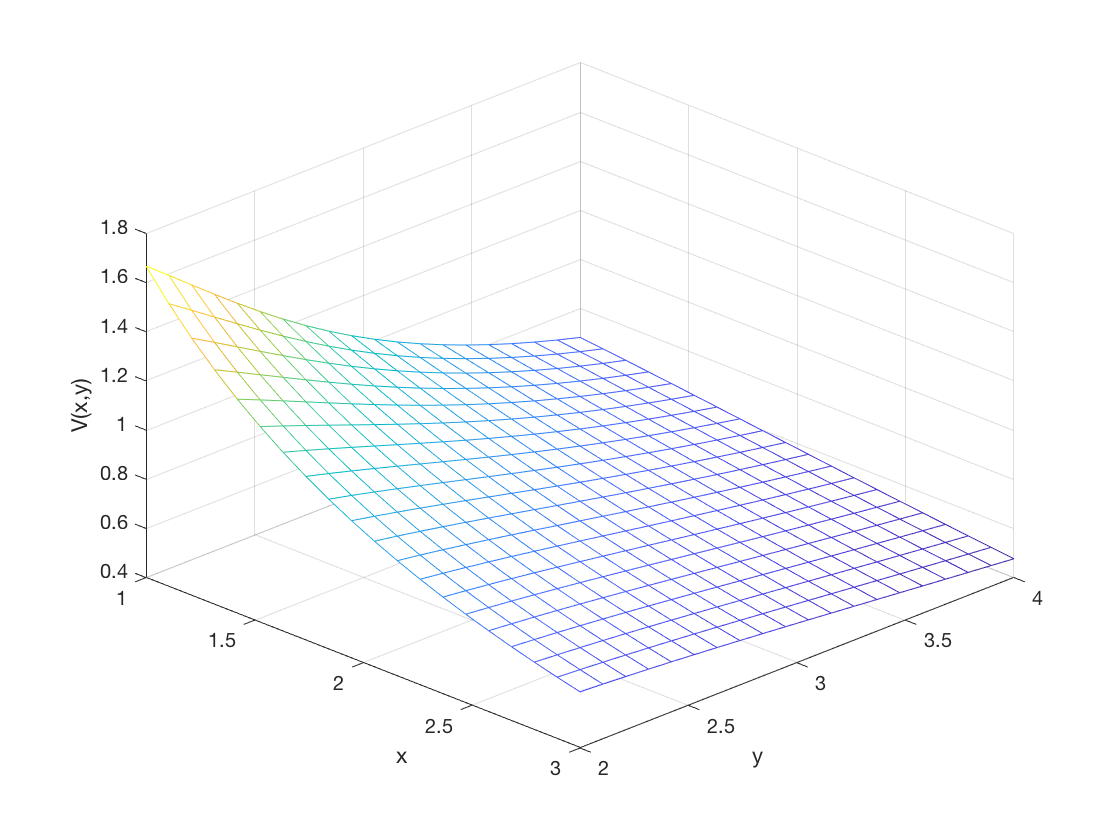

x=linspace(1,3,20);
y=linspace(2,4,20);
xp=linspace(0,1,50);
yp=linspace(1,2,50);

f1=@(x,y,xp) xp.^2 ./sqrt((x-xp).^2 + (y-1).^2);

f2=@(x,y,yp) yp ./sqrt(x.^2 + (y-yp).^2);

v=zeros(length(x),length(y));

for i = 1:length(x)
    for j= 1:length(y)
        
        v1=trapz(xp,f1(x(i),y(j),xp)) ; 
        v2=trapz(yp,f2(x(i),y(j),yp)) ; 
        v(j,i)=v1+v2;
        
    end    
    
end    



mesh(x,y,v)
xlabel('x')
ylabel('y')
zlabel('V(x,y)')
az = 45;
el=35;
view(az,el);

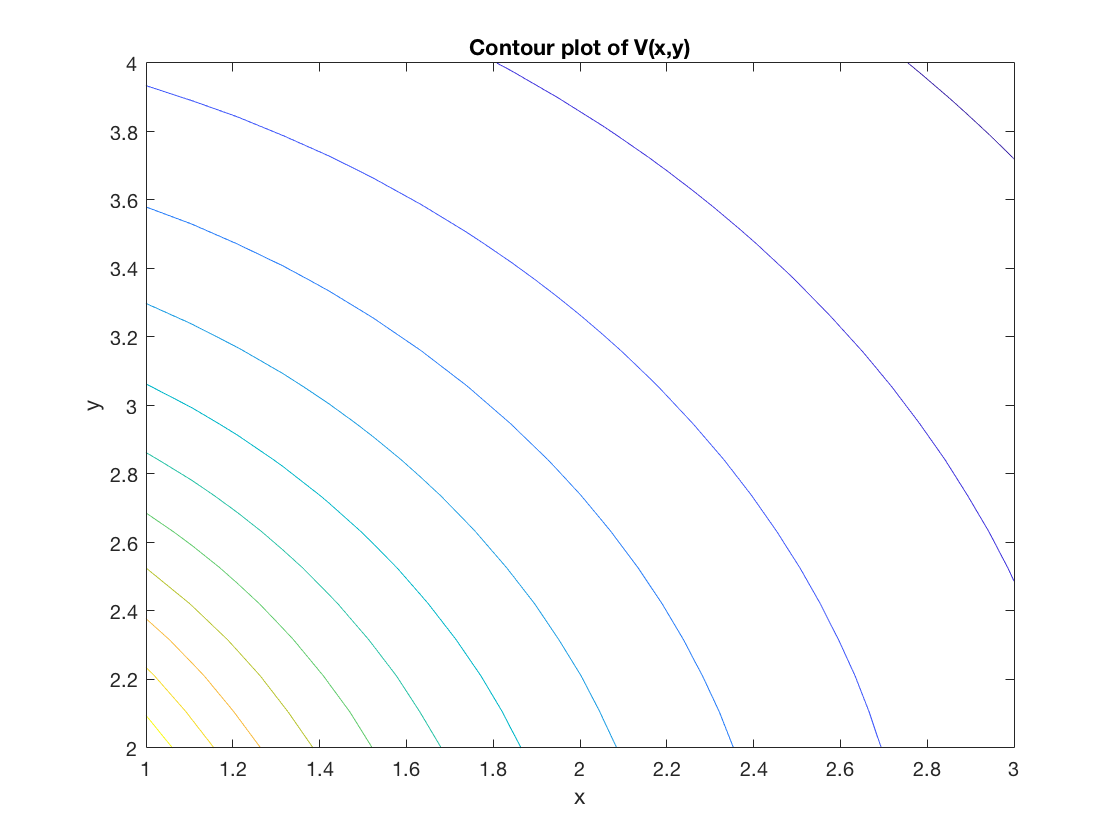


contour(x,y,v)
xlabel('x')
ylabel('y')
zlabel('V(x,y)')
title('Contour plot of V(x,y)')

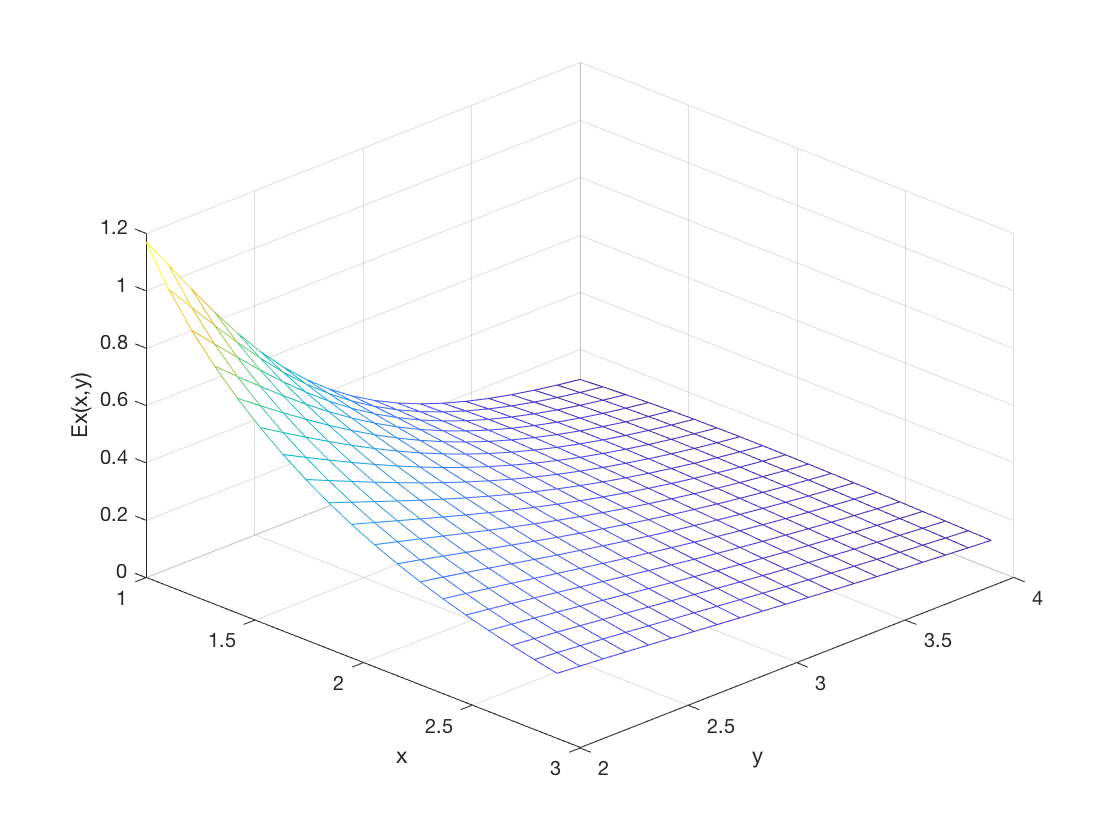



% electric field

Ey=-diff(v)./ .1 ;
Ex=-diff(v,1,2) /.1;

mesh(x(1:19),y,Ex)
xlabel('x')
ylabel('y')
zlabel('Ex(x,y)')
az = 45;
el=35;
view(az,el);

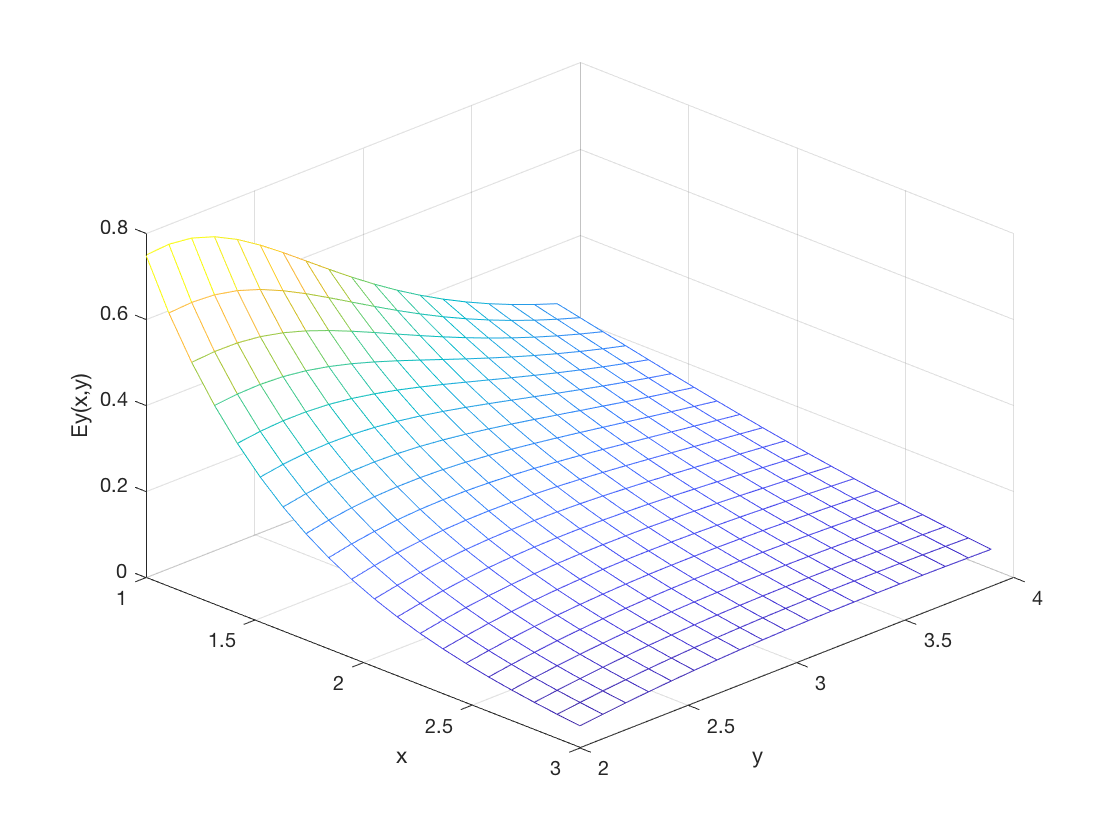



mesh(x,y(1:19),Ey)
xlabel('x')
ylabel('y')
zlabel('Ey(x,y)')
az = 45;
el=35;
view(az,el);

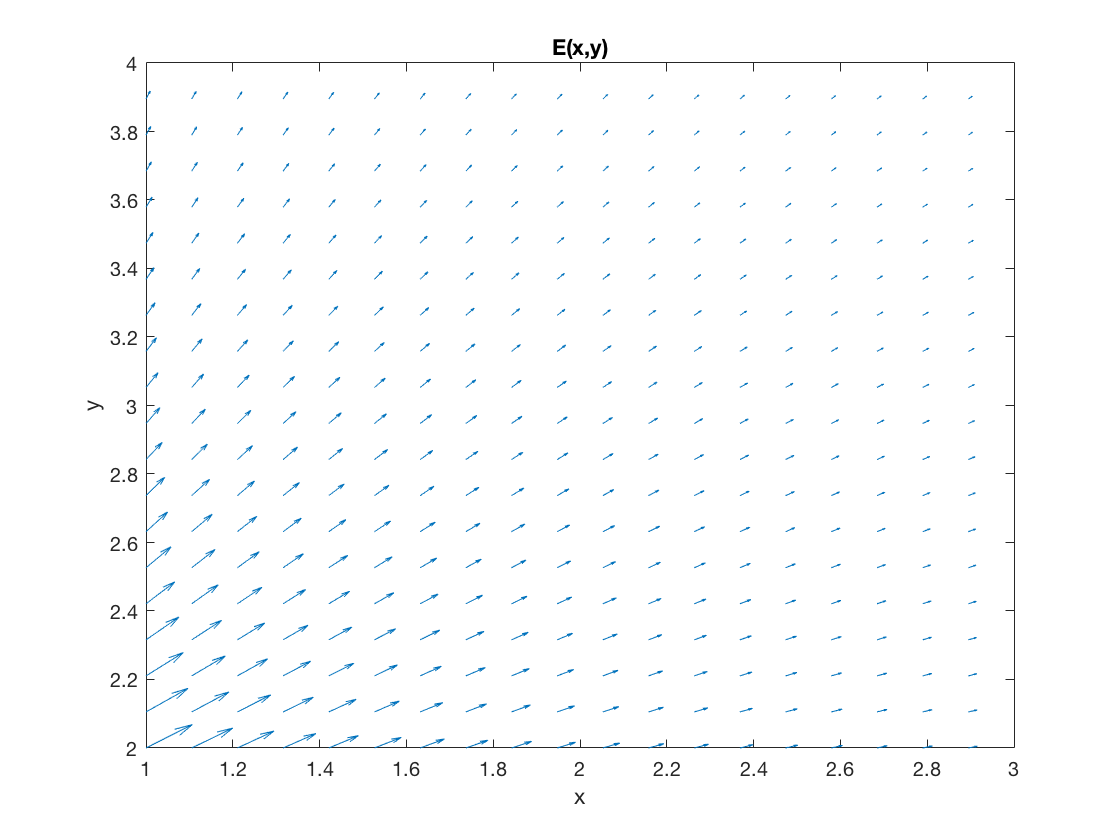

quiver(x(1:19),y(1:19),Ex(1:19,1:19),Ey(1:19,1:19))       
xlabel('x')
ylabel('y')
title ('E(x,y)')

**2D case: electric potential and electric field are calculated on a x-y plane at distance z above the disk (here z=2). **

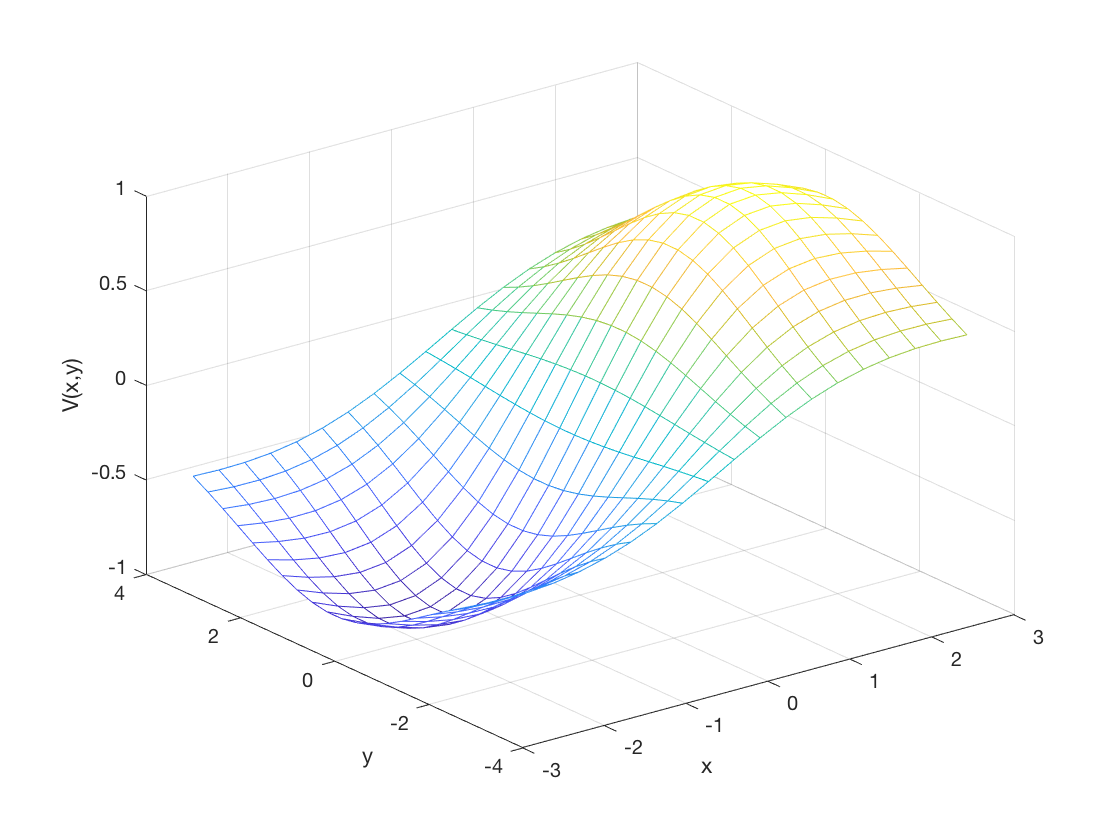

x=linspace(-3,+3,20);
y=linspace(-3,+3,20);
z=2;


v=zeros(length(x),length(y));

for i = 1:length(x)
    for j= 1:length(y)
        f=@ (r,t) cos(t) .* r.^2 ./sqrt((x(i)-r.*cos(t)).^2 + (y(j)-r.*sin(t)).^2 + z.^2);
        v(j,i)=integral2(f,0,2,0,2 .*pi) ; 
        
        
    end    

end    
 
mesh(x,y,v)
xlabel('x')
ylabel('y')
zlabel('V(x,y)')

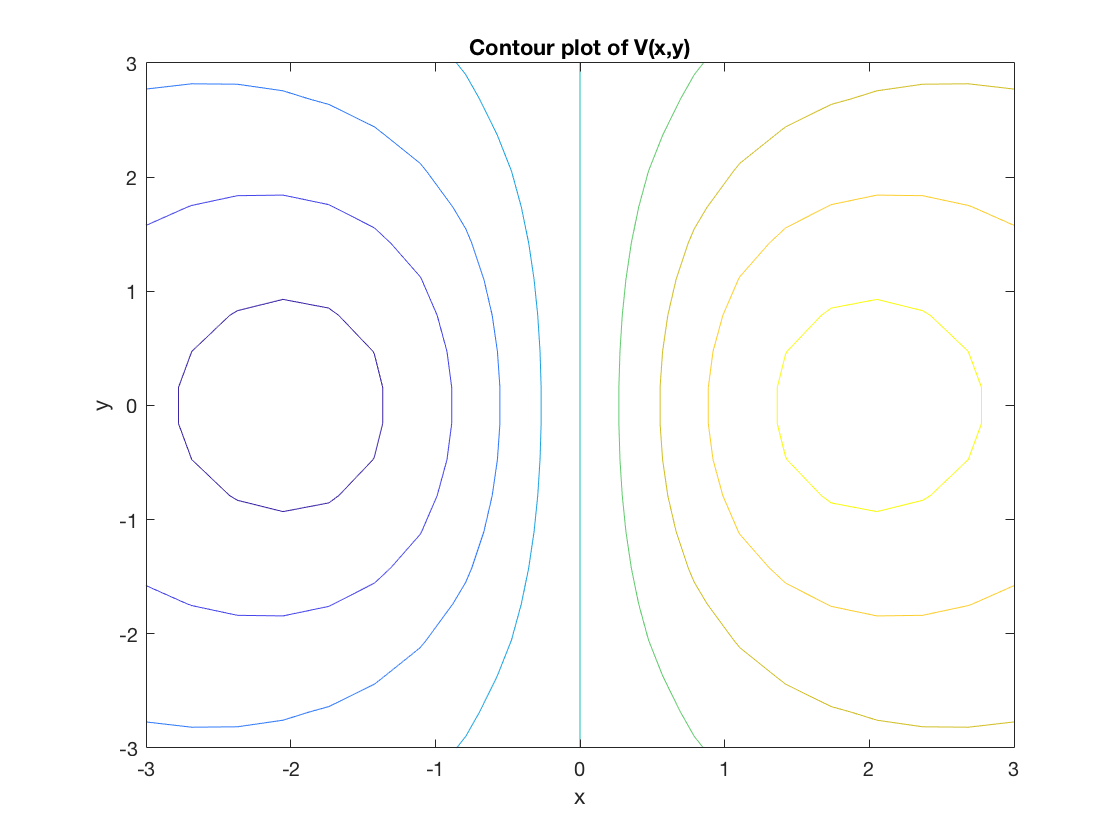


contour(x,y,v)
xlabel('x')
ylabel('y')
zlabel('V(x,y)')
title('Contour plot of V(x,y)')

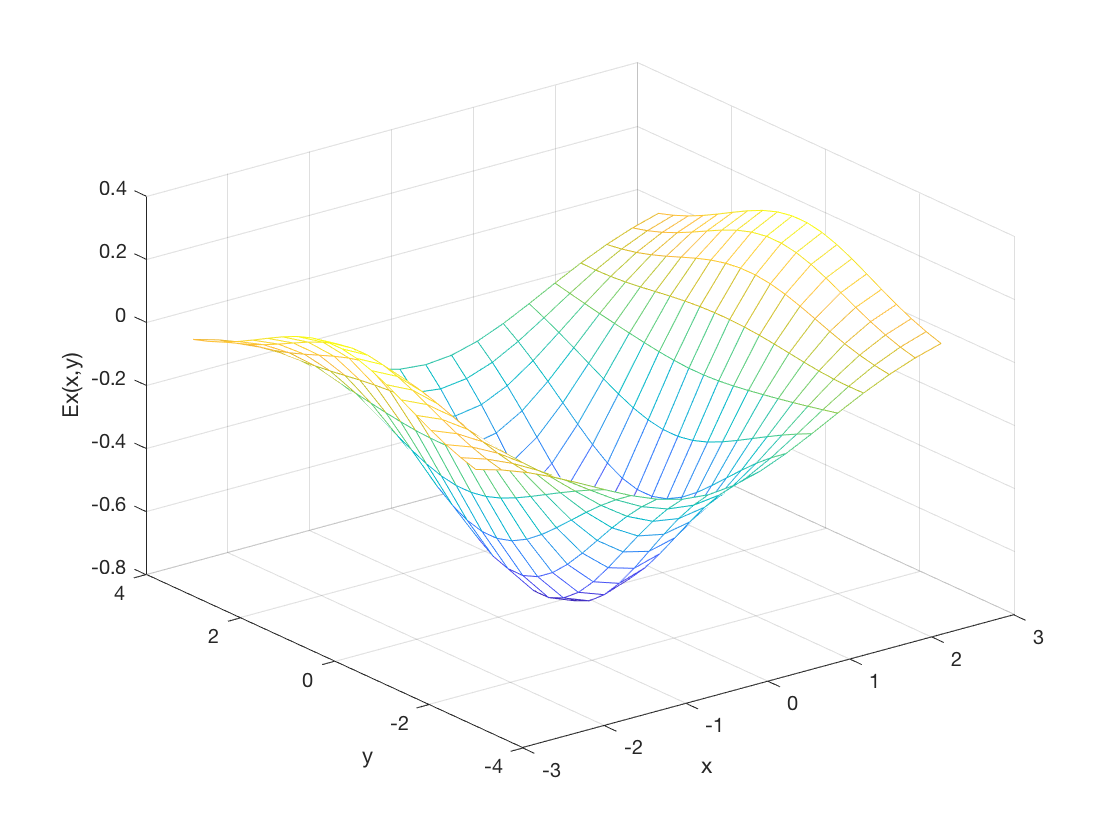




%electric field

Ey=-diff(v)./ .3 ;
Ex=-diff(v,1,2) /.3;   

mesh(x(1:19),y,Ex)
xlabel('x')
ylabel('y')
zlabel('Ex(x,y)')

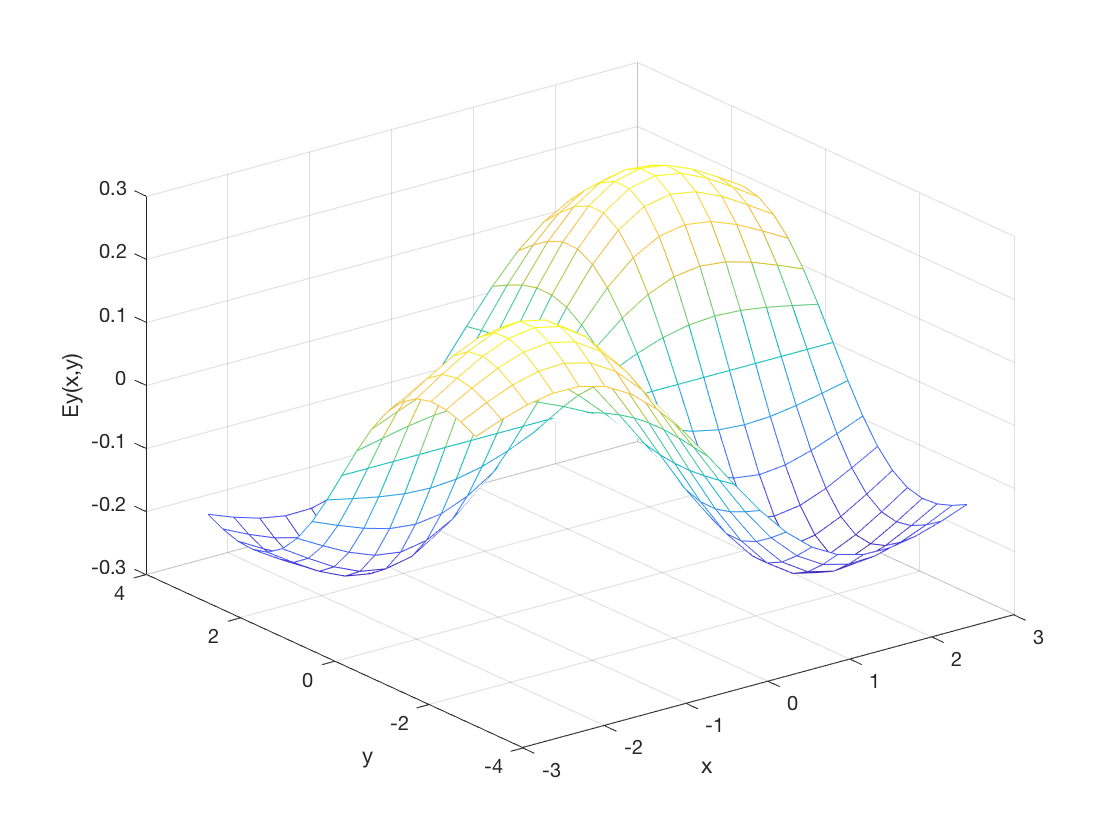



mesh(x,y(1:19),Ey)
xlabel('x')
ylabel('y')
zlabel('Ey(x,y)')

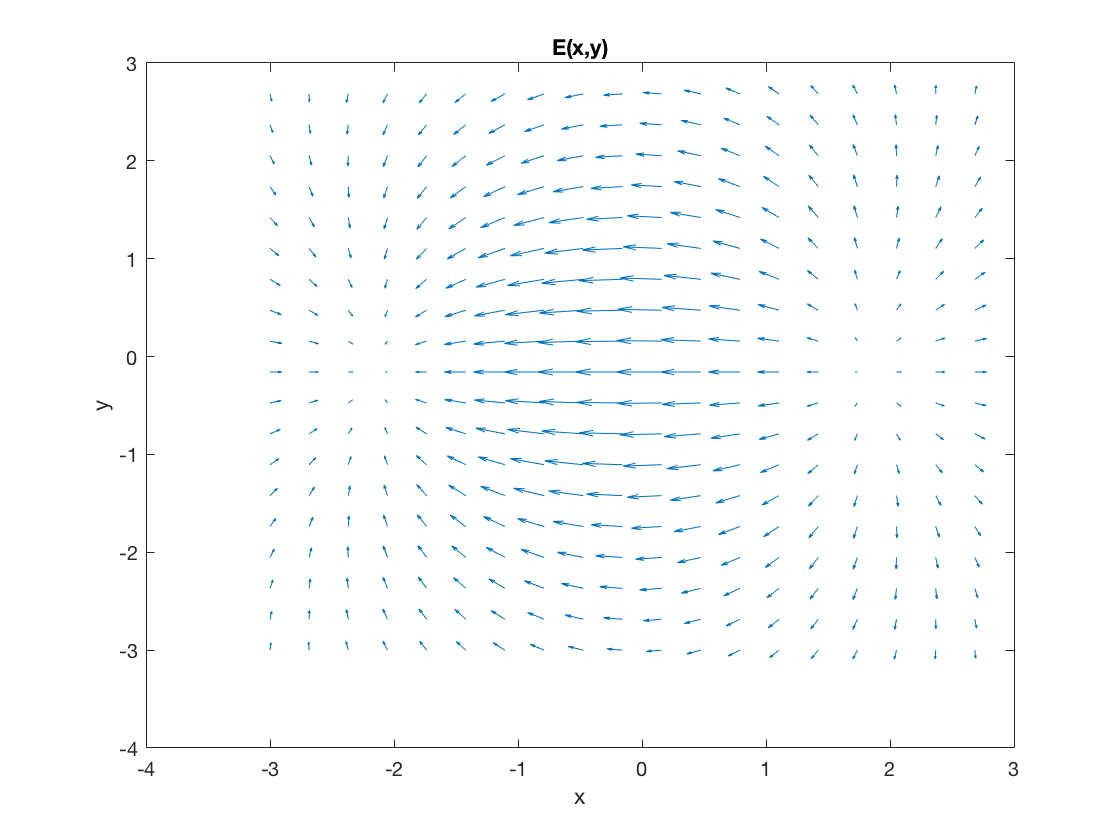


quiver(x(1:19),y(1:19),Ex(1:19,1:19),Ey(1:19,1:19))       
xlabel('x')
ylabel('y')
title ('E(x,y)')